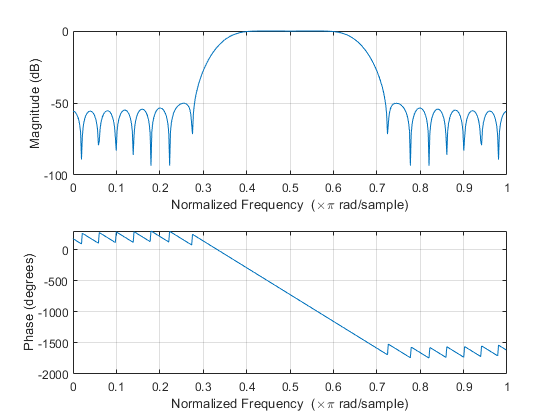

%FIR Bandpass Filter
% b = fir1(48,[0.35 0.65]); %48th order bandpass
% freqz(b,1,512) %magnitude (dB) and phase (degrees) vs w = 2*pi*f/fs rad/sample

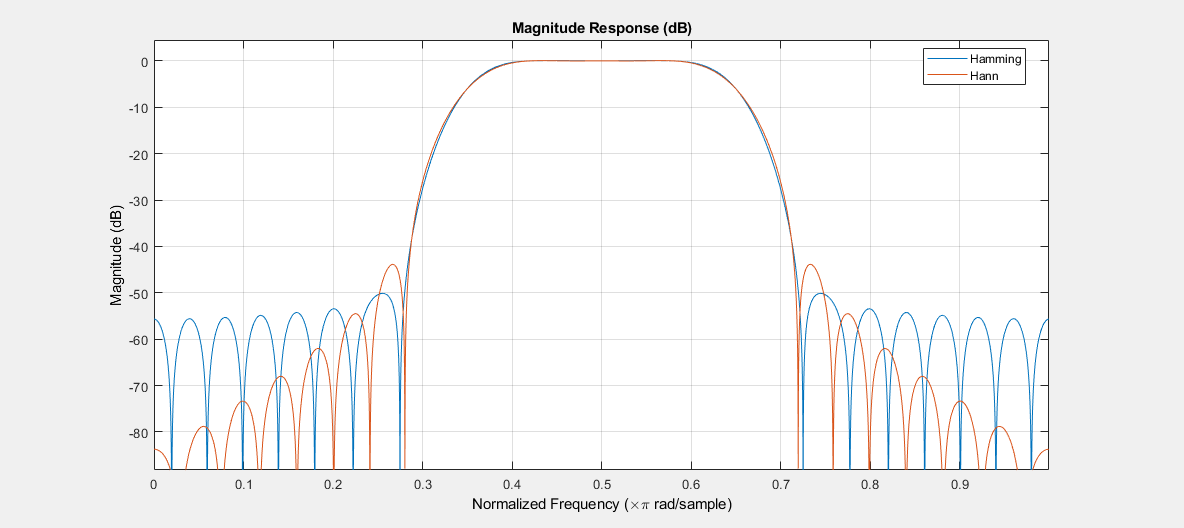

% 
% h = fir1(48,[0.35 0.65],hann(48+1)); %b using a Hann Window
% 
% hfvt = fvtool(b,1,h,1); %display compare Hamming and Hann window filter frequency response for magnitude
% legend(hfvt,'Hamming','Hann')

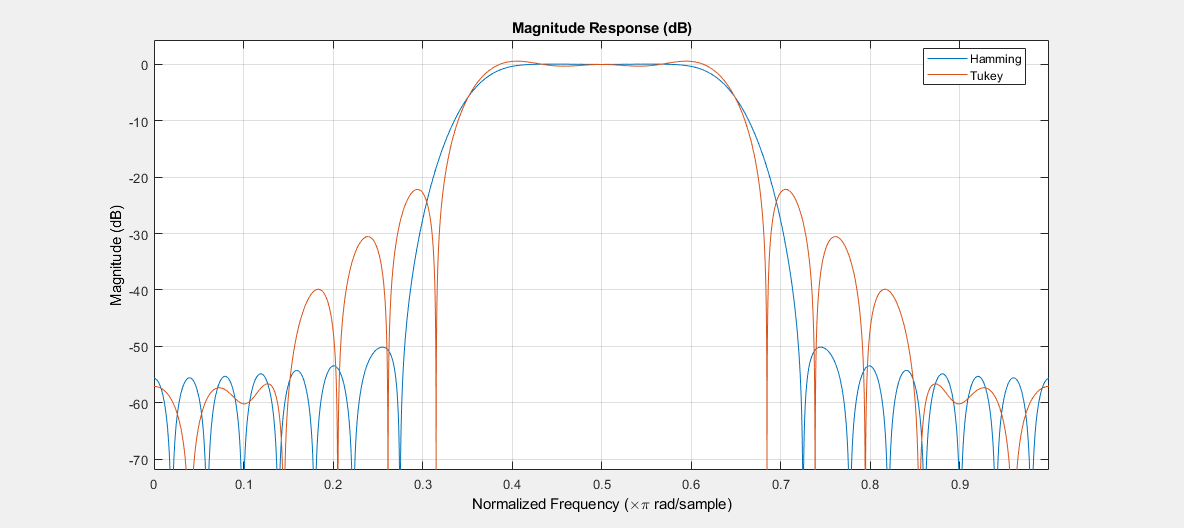

% 
% t = fir1(48,[0.35 0.65],tukeywin(48+1)); %b using a Tukey Window
% 
% hfvt = fvtool(b,1,t,1); %display compare Hamming and Tukey window filter frequency response for magnitude
% legend(hfvt,'Hamming','Tukey')

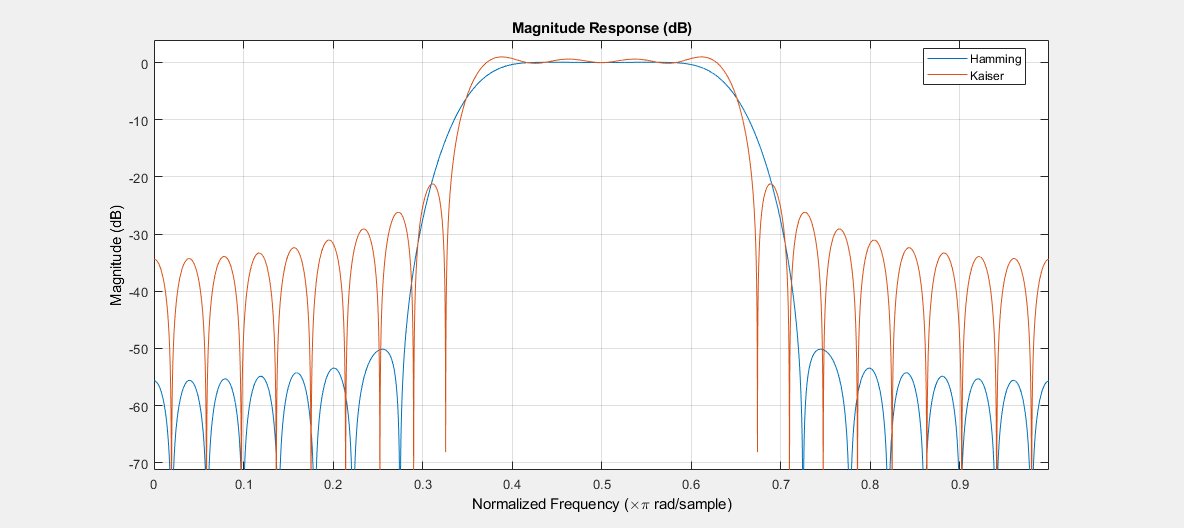

% 
% k = fir1(48,[0.35 0.65],kaiser(48+1)); %b using a Kaiser Window
% 
% hfvt = fvtool(b,1,k,1); %display compare Hamming and Kaiser window filter frequency response for magnitude
% legend(hfvt,'Hamming','Kaiser')


%FIR High-pass Filter and Low-Pass Filter
% load chirp.mat
% y %data
% Fs %8192 Hz sampling frequency
% t = (0:length(y)-1)/Fs; %time vector
% 
% b = fir1(34,0.48,'high',chebwin(35,30)); %34th order, wc = .48 rad, high-pass, chebwin window with 30 dB of ripple?
% freqz(b,1) %magnitude (dB) and phase (degrees) vs w = 2*pi*f/fs rad/sample
% 
% out = filter(b,1,y); %filters the input data x using a rational transfer function defined by the numerator and denominator coefficients b and a.
% 
% subplot(2,1,1)
% plot(t,y)
% title('Original Data')
% xlabel('Time (s)')
% ys = ylim
% 
% subplot(2,1,2)
% plot(t,out)
% title('Highpass Filtered Data')
% xlabel('Time (s)')
% ylim(ys)
% 
% b = fir1(34,0.48,chebwin(35,30)); %34th order, wc = .48pi, low-pass, chebwin window with 30 dB of ripple?
% 
% out = filter(b,1,y);
% 
% subplot(2,1,1)
% plot(t,y)
% title('Original Data')
% xlabel('Time (s)')
% ys = ylim
% 
% subplot(2,1,2)
% plot(t,out)
% title('Lowpass Filtered Data')
% xlabel('Time (s)')
% ylim(ys)
% 
% %Multiband FIR Filter
% ord = 46;
% 
% low = 0.4;
% bnd = [0.6 0.9];
% 
% bM = fir1(ord,[low bnd]); %nth order filter than attenuates frequencies below .4pi, and between .6pi and .9pi
% 
% bW = fir1(ord,[low bnd],'DC-1'); % DC-1 pass band
% 
% hfvt = fvtool(bM,1,bW,1); %display the filter frequency responsed
% legend(hfvt,'bM','bW')
% 
% hM = fir1(ord,[low bnd],'DC-0',hann(ord+1)); %bM using a Hann Window
% 
% hfvt = fvtool(bM,1,hM,1); %display compare Hamming and Hann window filter frequency response for magnitude
% legend(hfvt,'Hamming','Hann')
% 
% tW = fir1(ord,[low bnd],'DC-1',tukeywin(ord+1)); %bW using a Tukey Window
% 
% hfvt = fvtool(bW,1,tW,1); %display compare Hamming and Tukey window filter frequency response for magnitude
% legend(hfvt,'Hamming','Tukey')

%Definition of Decibel: In communication systems, gain is measured in bels;
%bels are used to measure the ration of two levels of power = power gain G = log P2/P1
%The decibel is 1/10 of a bel. G_dB = 10 log P2/P1.
%The dB value is a dimensionless measurement of the ratio of two values of interest that are the same type

